## 필터 설계

% 필터 스펙 설정
Fs = 500;          % 샘플링 주파수 (Hz)
Nyquist = Fs / 2;    % 나이퀴스트 주파수
Fstart = 1;         % 통과대역 주파수 (Hz)
Fend = 5;         % 통과대역 주파수 (Hz)

% FIR 필터 설계
order = 250; % 필터 차수
b = fir1(order, [Fstart/Nyquist,Fend/Nyquist], 'bandpass', kaiser(order+1, 0.5));

## 필터 응답 확인

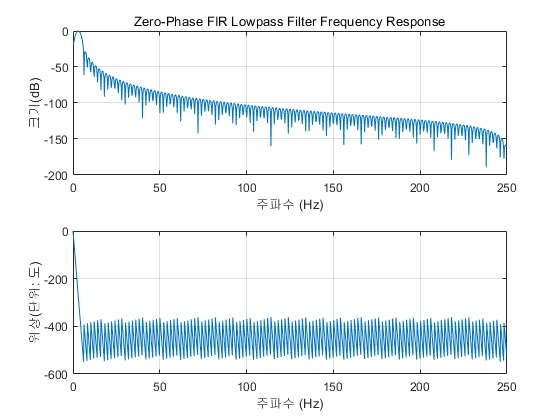

% 주파수 응답 플로팅
freqz(b, 1, 1024, Fs);
% 결과 표시
title('Zero-Phase FIR Lowpass Filter Frequency Response');

### 위상 응답 확인

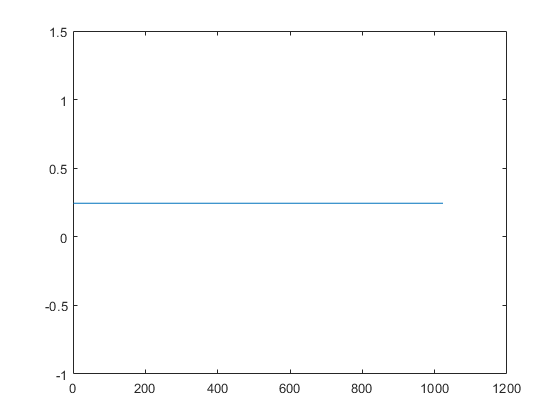

[h,w] = freqz(b, 1, 1024, Fs);
d = diff(w);
plot(d);

csvwrite("b.csv",b)

## 테스트

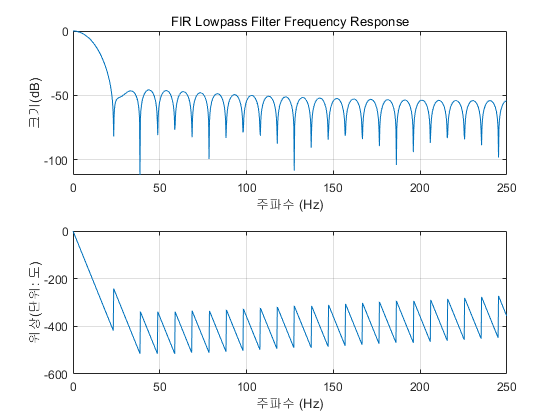

% FIR 필터 설계 예제(LOW)

% 필터 스펙 설정
Fs = 500;          % 샘플링 주파수 (Hz)
Nyquist = Fs / 2;    % 나이퀴스트 주파수
Fpass = 5;         % 통과대역 주파수 (Hz)

% FIR 필터 설계
order = 50; % 필터 차수
Wn = Fpass/Nyquist;
b = fir1(order, Wn, 'low', hamming(order+1));

% 주파수 응답 플로팅
freqz(b, 1, 1024, Fs);

% 결과 표시
title('FIR Lowpass Filter Frequency Response');

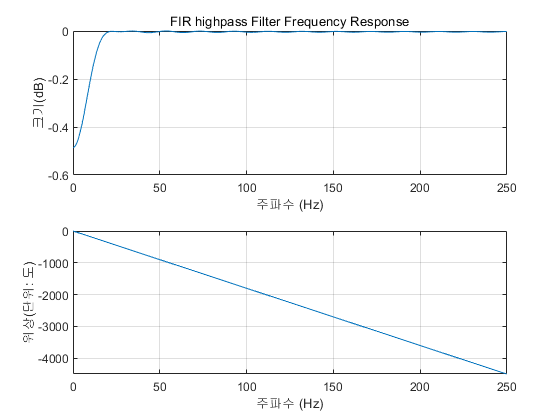

% FIR 필터 설계 예제(HIGH)

% 필터 스펙 설정
Fs = 500;          % 샘플링 주파수 (Hz)
Nyquist = Fs / 2;    % 나이퀴스트 주파수
Fpass = 0.5;         % 통과대역 주파수 (Hz)

% FIR 필터 설계
order = 50; % 필터 차수
Wn = Fpass/Nyquist;
b = fir1(order, Wn, 'high', hamming(order+1));

% 주파수 응답 플로팅
freqz(b, 1, 1024, Fs);

% 결과 표시
title('FIR highpass Filter Frequency Response');

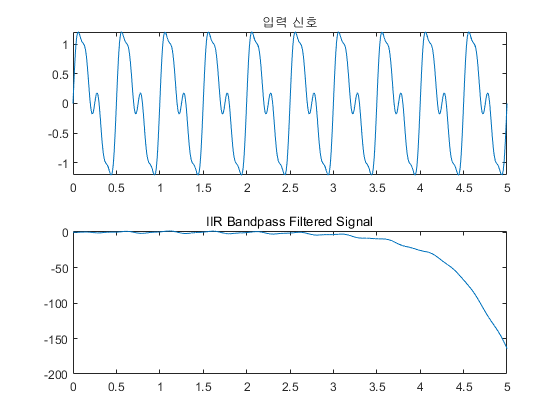

% IIR 대역통과 필터 설계 예제

% 필터 스펙 설정
Fs = 1000;          % 샘플링 주파수 (Hz)
Nyquist = Fs / 2;    % 나이퀴스트 주파수
Fpass1 = 1;          % 통과대역 시작 주파수 (Hz)
Fpass2 = 5;          % 통과대역 끝 주파수 (Hz)

% IIR 필터 설계
[b, a] = butter(4, [Fpass1/Nyquist, Fpass2/Nyquist], 'bandpass');

% 입력 신호 생성
t = 0:1/Fs:5;  % 5초 동안의 시간 벡터
x = sin(2*pi*2*t) + 0.5*sin(2*pi*4*t) + 0.2*sin(2*pi*8*t);

% IIR 필터링
y = filter(b, a, x);

% 결과 플로팅
figure;
subplot(2,1,1);
plot(t, x);
title('입력 신호');

subplot(2,1,2);
plot(t, y);
title('IIR Bandpass Filtered Signal');

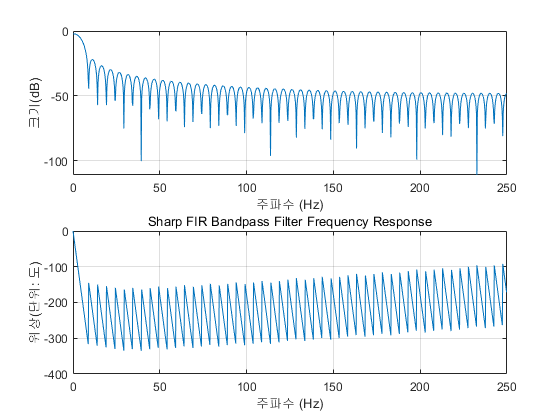

% 필터 스펙 설정
Fs = 500;          % 샘플링 주파수 (Hz)
Fpass1 = 1;          % 통과대역 시작 주파수 (Hz)
Fpass2 = 5;          % 통과대역 끝 주파수 (Hz)

% 필터 주파수 범위 및 이상적인 응답 생성
freqRange = [0 Fpass1 Fpass1 Fpass2 Fpass2 Fs/2];
idealResponse = [0 0 1 1 0 0];

% 최소제곱법으로 FIR 필터 설계
order = 100; % 필터 차수
filterCoeff = firls(order, freqRange/(Fs/2), idealResponse);

% 주파수 응답 플로팅
freqz(filterCoeff, 1, 1024, Fs);

% 결과 표시
title('Sharp FIR Bandpass Filter Frequency Response');

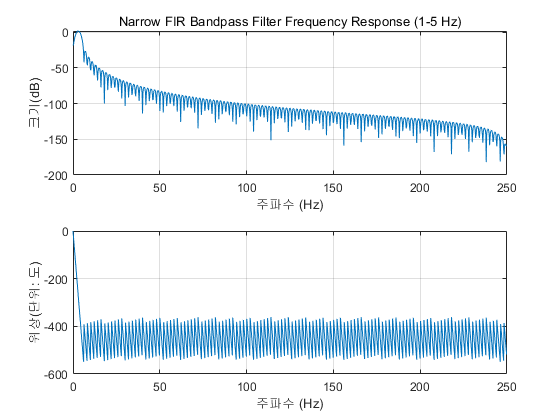

% 필터 스펙 설정
Fs = 500;          % 샘플링 주파수 (Hz)
Fpass1 = 1;         % 통과대역 시작 주파수 (Hz)
Fpass2 = 5;         % 통과대역 끝 주파수 (Hz)

% 필터 주파수 범위 및 이상적인 응답 생성
freqRange = [0 Fpass1 Fpass1 Fpass2 Fpass2 Fs/2];
idealResponse = [0 0 1 1 0 0];

% 최소제곱법으로 FIR 필터 설계
order = 250; % 필터 차수
filterCoeff = firls(order, freqRange/(Fs/2), idealResponse);

% 주파수 응답 플로팅
freqz(filterCoeff, 1, 1024, Fs);

% 결과 표시
title('Narrow FIR Bandpass Filter Frequency Response (1-5 Hz)');